function [X_Est, P_Est, GT] = myEKF(out)
    % Initial State
    x0 = [out.GT_position.signals.values(1,1), out.GT_position.signals.values(1,2), 0, 0, 0]'; 
    ekf = extendedKalmanFilter(@fState,@hMeasure,x0);

    % Covariance tuning (you’ll want to tune these later)
    ekf.StateCovariance = eye(5)*0.1;
    ekf.ProcessNoise = diag([0.01, 0.01, 0.01, 0.1, 0.1]); 
    ekf.MeasurementNoise = eye(3)*0.05;

    % Preallocate
    N = length(out.Sensor_Time);
    X_Est = zeros(N,5);
    P_Est = zeros(5,5,N);

    % Sync sensor data (you may want to resample in practice)
    acc = out.Sensor_ACCEL.signals.values;
    gyro = out.Sensor_GYRO.signals.values(:,3); % yaw rate
    dt = mean(diff(out.Sensor_Time.signals.values)); % ~0.0098s

    % Clean ToF data: use only distance
    ToF1 = out.Sensor_ToF1.signals.values(:,1);
    ToF2 = out.Sensor_ToF2.signals.values(:,1);
    ToF3 = out.Sensor_ToF3.signals.values(:,1);

    for k = 1:N
        u = [acc(k,1); acc(k,2); gyro(k)];
        z = [ToF1(k); ToF2(k); ToF3(k)];

        predict(ekf, u);
        correct(ekf, z);

        X_Est(k,:) = ekf.State';
        P_Est(:,:,k) = ekf.StateCovariance;
    end

    GT = out.GT_position.signals.values(:,1:3); % [x, y, z]
end

%% Process model
function xNext = fState(x,u)
    dt = 0.0098; % or dynamically estimate
    yaw = x(3);
    acc_body = u(1:2); 
    omega = u(3);

    R = [cos(yaw), -sin(yaw); sin(yaw), cos(yaw)];
    acc_world = R * acc_body;

    % State update
    xNext = zeros(5,1);
    xNext(1) = x(1) + x(4)*dt + 0.5*acc_world(1)*dt^2;
    xNext(2) = x(2) + x(5)*dt + 0.5*acc_world(2)*dt^2;
    xNext(3) = x(3) + omega*dt;
    xNext(4) = x(4) + acc_world(1)*dt;
    xNext(5) = x(5) + acc_world(2)*dt;
end

%% Measurement model
function z = hMeasure(x)
    % Approximate wall positions (you should replace with actual arena layout)
    % Assuming square room, walls at x=0, x=2.4, y=0, y=2.4
    x_pos = x(1);
    y_pos = x(2);
    yaw = x(3);

    % ToF1: forward-facing
    z1 = 2.4 - y_pos; % distance to forward wall

    % ToF2: left-facing
    z2 = x_pos; % distance to left wall

    % ToF3: right-facing
    z3 = 2.4 - x_pos; % distance to right wall

    z = [z1; z2; z3]; 
end


clear; clc;

% Convert quaternion to Euler angles
data = load("trainingData/calib1_rotate.mat")

data = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


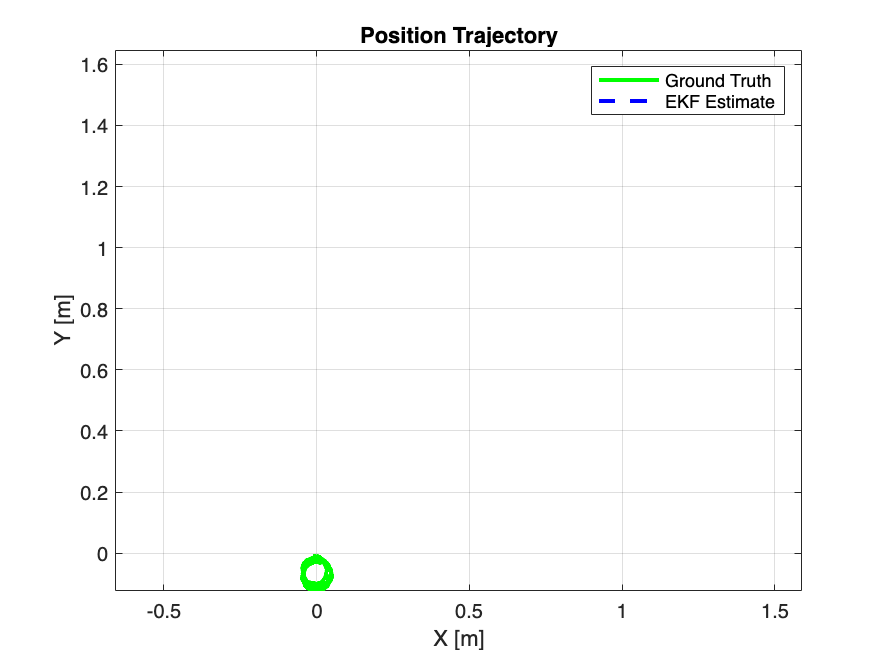



[X_Est, P_Est, GT] = myEKF(data.out);
eul = quat2eul(data.out.GT_rotation.signals.values); % ZYX order
GT_yaw = eul(:,1); % Yaw is rotation around Z

figure;
plot(GT(:,1), GT(:,2), 'g-', 'LineWidth', 2); hold on;
plot(X_Est(:,1), X_Est(:,2), 'b--', 'LineWidth', 2);
xlabel('X [m]');
ylabel('Y [m]');
legend('Ground Truth','EKF Estimate');
title('Position Trajectory');
grid on;
axis equal;

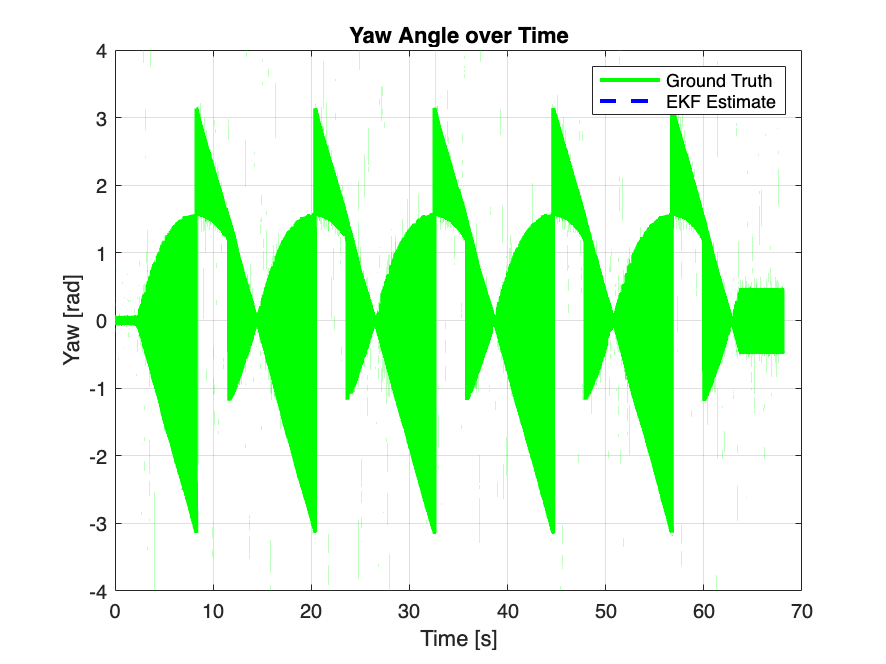


figure;
time = squeeze(data.out.Sensor_Time.signals.values);

plot(time, GT_yaw, 'g-', 'LineWidth', 2); hold on;
plot(time, X_Est(:,3), 'b--', 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Yaw [rad]');
legend('Ground Truth','EKF Estimate');
title('Yaw Angle over Time');
grid on;